# **Introduction to reinforcement learning - hands on**

**Come to our RL reading group on Wednesdays, 3-4 PM at Soltani Lab! **

**Bi-weekly, this week Oct 25**

# **I. Concepts: Reward, action, agent, environment**

**Policy: defines a probability of choosing an action (can be based on the action value or not).**

**greedy, epsilon-greedy, or softmax as three examples (exploration versus exploitation)**

**greedy can stuck at local minima**

- softmax**: **$\Pr \left(a_i \right)=\frac{e^{\left(\frac{V\left(a_i \right)}{\sigma }\right)} }{\sum_i e^{\left(\frac{V\left(a_j \right)}{\sigma }\right)} }$

- epsilon-greedy: $\left\lbrace \begin{array}{ll}
\max \;V\left(a\right) & \textrm{with}\;\textrm{probability}\;1-\epsilon \\
\textrm{any}\;\textrm{other}\;\textrm{actions} & \textrm{with}\;\textrm{probability}\;\epsilon 
\end{array}\right.$

**Or no action (e.g., when you are learning the value of painful stimulus without doing any actions)**

**From Sutton and Barto**

**Policy:**

- **defines the learning agent’s way of behaving at a given time. **

- **a mapping from perceived states of the environment to actions to be taken when in those states. **

- **It corresponds to what in psychology would be called a set of stimulus–response rules or associations. **

- **The policy is the core of a reinforcement learning agent in the sense that it alone is sufficient to determine behavior. **

- **In general, policies may be stochastic, specifying probabilities for each action.**

**Reward signal:**

- **defines the goal of a reinforcement learning problem. **

- **On each time step, the environment sends to the reinforcement learning agent a single number called the reward. The agent’s sole objective is to maximize the total reward it receives over the long run. The reward signal thus defines what are the good and bad events for the agent. They are the immediate and defining features of the problem faced by the agent. **

- **The reward signal is the primary basis for altering the policy; if an action selected by the policy is followed by low reward, then the policy may be changed to select some other action in that situation in the future. **

- **In general, reward signals maybe stochastic functions of the state of the environment and the actions taken.**

**Value function:**

- **as opposed to the immediate signal of a reward, value functions specify what is good in the long run. **

- **Roughly speaking, the value of a state is the total amount of reward an agent can expect to accumulate over the future, starting from that state. **

- **Whereas rewards determine the immediate, intrinsic desirability of environmental states, values indicate the long-term desirability of states after taking into account the states that are likely to follow and the rewards available in those states. **

- **        For example, a state might always yield a low immediate reward but still have a high value because it is regularly followed by other states that yield high rewards. Or the reverse could be true. **

**Action choices**

- **Action choices are made based on value judgments. **

- **We seek actions that bring about states of highest value, not highest reward, because these actions obtain the greatest amount of reward for us over the long run.**

- **Unfortunately, it is much harder to determine values than it is to determine rewards. Rewards are basically given directly by the environment, but values must be estimated and re-estimated from the sequences of observations an agent makes over its entire lifetime. **

- **In fact, the most important component of almost all reinforcement learning algorithms we consider is a method for efficiently estimating values. The central role of value estimation is arguably the most important thing that has been learned about reinforcement learning over the last six decades.**

**Model of the environment**

- **This is something that mimics the behavior of the environment, or more generally, that allows inferences to be made about how the environment will behave.**

- **For example, given a state and action, the model might predict the resultant next state and next reward. **

- **Models are used for planning, by which we mean any way of deciding on a course of action by considering possible future situations before they are actually experienced. **

- **Methods for solving reinforcement learning problems that use models and planning are called model-based methods, as opposed to simpler model-free methods that are explicitly trial-and-error learners—viewed as almost the opposite of planning. **

# **II. Single-state environment:**

The RW model encapsulates the most basic type of value-based, error-driven learning. A running internal estimate of value at each time step is denoted $V\left(t\right)$.  $V\left(t\right)$ is updated based on an error signal, or Prediction Error (PE) -- the difference between observed reward $R_t$ and $V\left(t\right)$.

Learning proceeds gradually, as a function of the learning rate $\alpha$. so that the internal model of value learns to track the long-term running average. If $\alpha =0$ there is no learning. If $\alpha =1$then the agent's expected value is simply the previous reward $R \ldotp \;$

This equation describes the agent's learning process: 


$$V\left(t+1\right)=V\left(t\right)+\alpha \left(R_t -V\left(t\right)\right)$$


$R$can be generalized to any experience imbued with value.  i.e., it could be a punishment.

This framework can be used to model learning of the values associated with a set of cues, options, or actions.  It is a generic learning mechanism, and can also be used to assign value to states. 

Typically, the agent has one internal value representation $V$for each cue, option, or action. 

The example below explores this using a 2-armed Bandit problem (simlar to the active inference problem that we were dealing with in the previous module). in a 2-choice task (i.e., choose blue vs. choose red), the agent would typically have two value representations for each of the 2 options, i.e.,  $V_{\textrm{blue}} \left(t\right)$ and $V_{\textrm{red}} \left(t\right)$.  When the agent experiences a reward, the value associated with the reward is updated. 

Note that in all RW models, there is no representation of future states or transitions across states. There is only experienced reward (or punishment) and assignment of credit to a linked cue/action/etc. 

## **A. Rescorla-Wagner**


$$V\left(t+1\right)=V\left(t\right)+\alpha \left(R_t -V\left(t\right)\right)$$


**Reversal learning task with Rescorla Wagner model:**

# 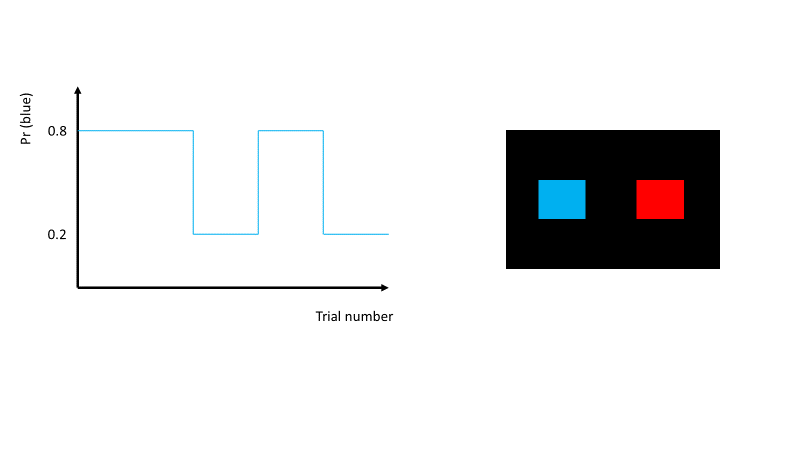

**Let's code the simulated behavior!**

setting up the environment and agent parameter:

clear
% define the enviornment:
option_blue=[ones(100,1)*0.8;ones(30,1)*0.2;ones(30,1)*0.8;ones(30,1)*0.2];
option_red=1-option_blue;
% define learning rate: 
alpha =0.5

alpha = 0.5000

% define the inverse temprature for the softmax policy:
beta = 0

beta = 0

decision making and learning:

rng('shuffle');
% we assume that values for blue and red options are learned:
V_blue = 0.5*ones(length(option_blue)+1,1);
V_red = 0.5*ones(length(option_red)+1,1);

for ii=1:length(option_blue)

    % decision making (let's assume that the agent uses softmax policy)
    Pr_blue(ii) = exp(V_blue(ii)*beta)/(exp(V_blue(ii)*beta)+exp(V_red(ii)*beta));
    if rand < Pr_blue(ii)
        choice(ii)=1; % 1 is blue and 0 is red
    else
        choice(ii)=0;
    end

    % Reward
    if choice(ii)==1
        R(ii) = rand < option_blue(ii);
    else
        R(ii) = rand < option_red(ii);
    end

    % learning
    if choice(ii)==1 % if the blue option has been chosen
        V_blue(ii+1)=V_blue(ii)+alpha*(R(ii)-V_blue(ii));
        V_red(ii+1)=V_red(ii);
    else
        V_blue(ii+1)=V_blue(ii);
        V_red(ii+1)=V_red(ii)+alpha*(R(ii)-V_red(ii));
    end

end

Now let's have a look at the generated behavior:

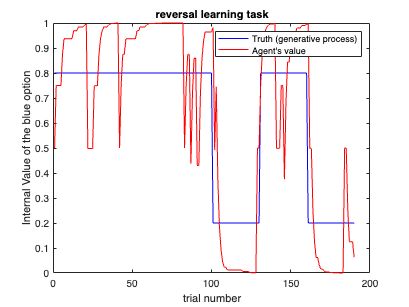

figure
plot(option_blue,'b')
ylim([0,1])
title('reversal learning task')
ylabel('Internal Value of the blue option')
xlabel('trial number')
hold on
plot(V_blue(1:end-1),'r') % also, do this for Pr_blue and choice
legend({'Truth (generative process)' 'Agent''s value'})

#### Questions to answer

- What do you predict the effect of increasing beta to be?  Why?

- What do you predict the effect of increasing alpha to be?  Why?

        Extend the simulation to plot Probability of choosing blue, choice, and reward. 

         3. What values of alpha and beta would maximize reward, approximately?  Why?

# **III. Multi-state environment **

RW provides a basic learning mechanism -- error driven learning. Often, rewards are associated with **states** ($s$) and **actions** (A). We can think of states as locations on a grid, but the concept is used very generally to refer to any set of environmental constraints or any set of context variables. Representing states becomes useful when different states are associated with different reward contingencies. e.g., one location in a maze may contain food, and another may not.  

States are also associated with the ability to transition to other, future states. This is usually represented probabilistically in terms of a state transition matrix.  They are also associated with actions. For example, in a "food-present" state you may be able to take the action "eat", but in a "food-absent" state this action is not available. $V\left(s\right)$represents the expected value at state $s$. $V\left(s\right)$includes an internal representation of the expected current and future reward from all future states. Future rewards are often discounted based on how many transitions (e.g., time steps) are required to obtain the reward. Thus:


$$V\left(s\left(t\right)\right)=E\left\lbrack R\left(t+1\right)+\gamma R\left(t+2\right)+\gamma^2 R\left(t+3\right)+\ldotp \ldotp \ldotp \right\rbrack$$
 

$Q\left(s,a\right)$represents the value of a particular action $a$ action in a particular state $s$ . 

**V (state value) and Q (state-action value) matrices: **

- **V(s) and Q(s,a)**

- **    White circle: state**

- **    Black circle: reward**

- **    T: termination of states**

- **    each arm: action**

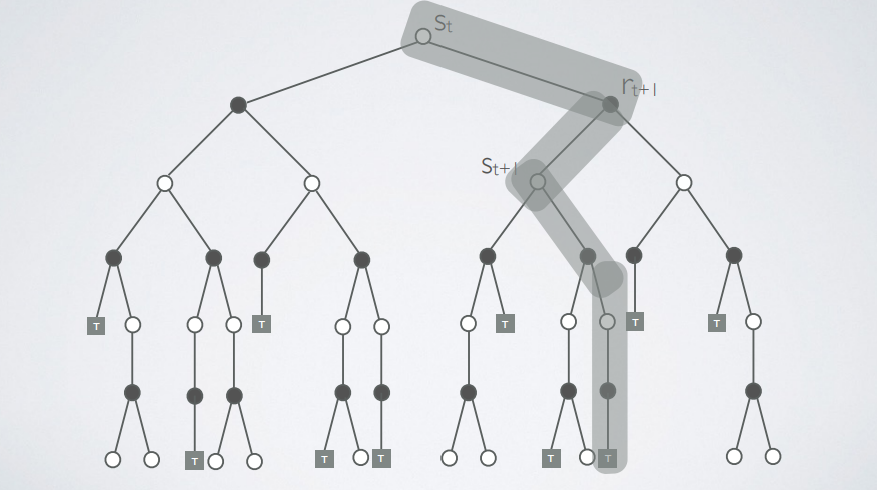

**policy: probability of choosing actions in each state (state-dependent), **

**In QL or SARSA: mapping the Q values into the probability of choosing an action. **

- **RL policy vs active inference policy**

## **A. model free versus model based**

**What is a model? a model predicts what the environment does in the next step!**

Note that in all RW models, there is no representation of future states or transitions across states. There is only experienced reward (or punishment) and assignment of credit to a linked cue/action/etc.  The lack of explicit representation of future states and contingencies makes the learning "model free". 

**In model-based learning, the agent knows (or learns) the model of the environment (i.e., state transition probabilities,  expected reward proababilities, etc).**

## 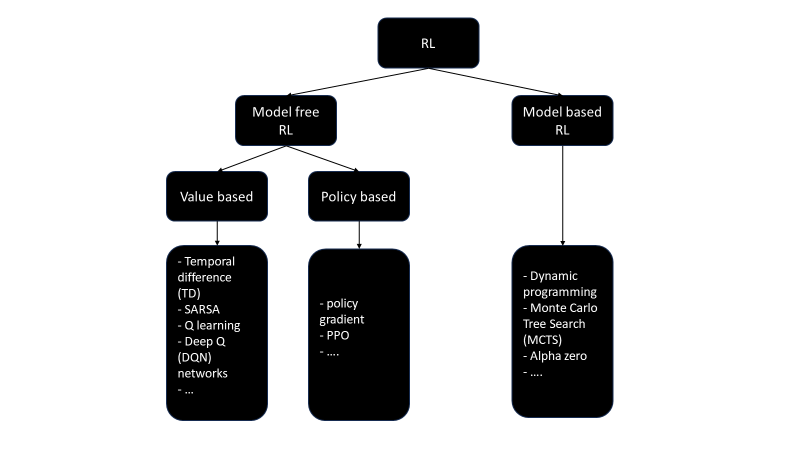

## **B. TD learning (model free)**

**The overarching value function is listed as:**


$$V\left(S_t \right)=V\left(S_t \right)+\alpha \left(r_{t+1} +\gamma V\left(S_{t+1} \right)-V\left(S_t \right)\right)$$


**Benefits of TD learning**

- more biologically plausible RPEs or value (Dopaminergic system)

**Question: How is the RPE is different in TD learning versus Rescorla-Wagner?**

**It is actually the same concept! But how?**

- **B.1. Q learning: assumes that no matter my policy is and no matter whether I choose the best action or not, I will use the best action value to update my estimate! (off-policy)**

-     
$$Q\left(S_t ,A_t \right)=Q\left(S_t ,A_t \right)+\alpha \left(r_{t+1} +\gamma \max_a Q\left(S_{t+1} ,a\right)-Q\left(S_t ,A_t \right)\right)$$


- **B.2. SARSA: the update is being done based on the value of an action that the agent chose (on-policy), i.e., incroporating the agent's own experience into learning. **

-     
$$Q\left(S_t ,A_t \right)=Q\left(S_t ,A_t \right)+\alpha \left(r_{t+1} +\gamma Q\left(S_{t+1} ,A_{t+1} \right)-Q\left(S_t ,A_t \right)\right)$$


- **Note: If policy is greedy, SARSA and QL will be the same**

**comparison between the SARSA and QL:**

- "QL directly learns the optimal policy while SARSA learns a “near” optimal policy. QL is a more aggressive agent, while SARSA is more conservative. An example is walking near the cliff. QL will take the shortest path because it is optimal (with the risk of falling), while SARSA will take the longer, safer route (to avoid unexpected falling)."

- "In practice, if you want to fast in a fast-iterating environment, QL should be your choice. However, if mistakes are costly (unexpected minimal failure — robots), then SARSA is the better option." Medium Website. 

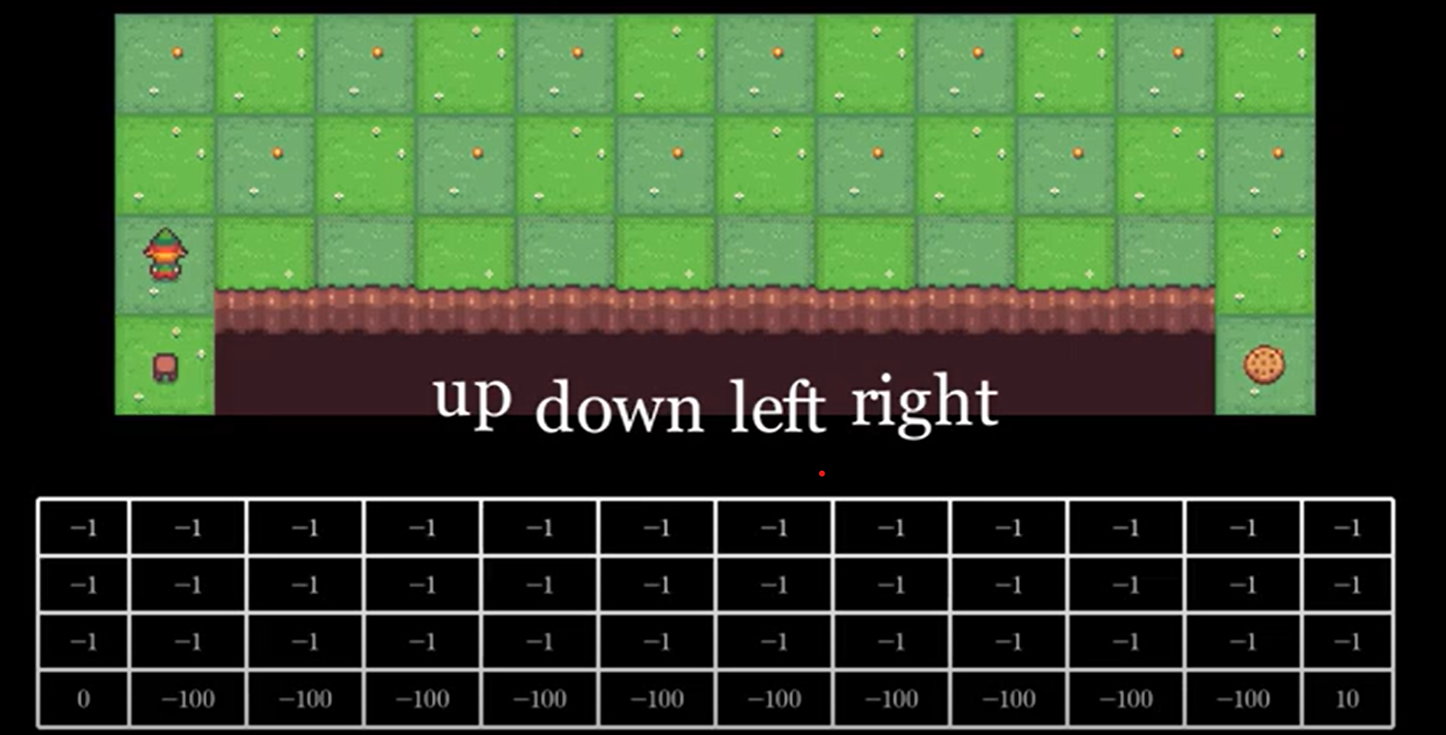

**Deep Q-Learning if the space is too large!**